clc
clear all
close all
h=0.25:0.25:1.5

h =    0.250000000000000   0.500000000000000   0.750000000000000   1.000000000000000   1.250000000000000   1.500000000000000


e=[60,120,180,210,225,230]

e =     60   120   180   210   225   230



I=1./h

I =    4.000000000000000   2.000000000000000   1.333333333333333   1.000000000000000   0.800000000000000   0.666666666666667


E=1./e

E =    0.016666666666667   0.008333333333333   0.005555555555556   0.004761904761905   0.004444444444444   0.004347826086957


t=table(I',E','VariableNames',{'I','E'})

t = 6×2 table
            I                     E         
    _________________    ___________________

                    4     0.0166666666666667
                    2    0.00833333333333333
     1.33333333333333    0.00555555555555556
                    1    0.00476190476190476
                  0.8    0.00444444444444444
    0.666666666666667    0.00434782608695652


n=1

n =      1


I_s=zeros(n+1);
for i=1:(n+1)
    for j=1:(n+1)
    I_s(i,j)=(sum(I.^((i+j)-2)));
    end
end

E_s=zeros(n+1,1);
for i=1:(n+1)
    E_s(i,1)=(sum((I.^(i-1)).*E));
end
I_s

I_s =    6.000000000000000   9.799999999999999
   9.799999999999999  23.862222222222222


E_s

E_s =    0.044109730848861
   0.101956751782839


A=pinv(I_s)*E_s

A =    0.001132532507909
   0.003807605694021



alfa=1/A(1,1)

alfa =      8.829768620471294e+02


beta=A(2,1)*alfa

beta =    3.362027727619485



plot(h,e,'o') 
hold on;

y=(alfa.*h)./(beta+h)

y = 	1.0e+02 *

   0.611136547551545   1.143151893670359   1.610477094031473   2.024234867780176   2.393136257505982   2.724100657729425


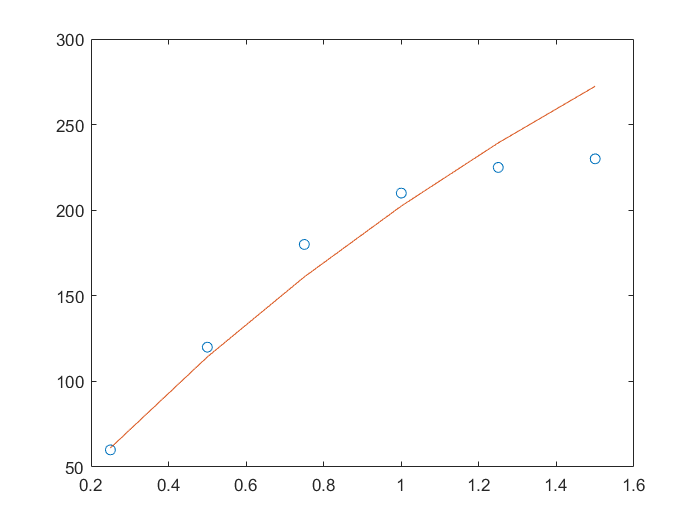


plot(h,y)